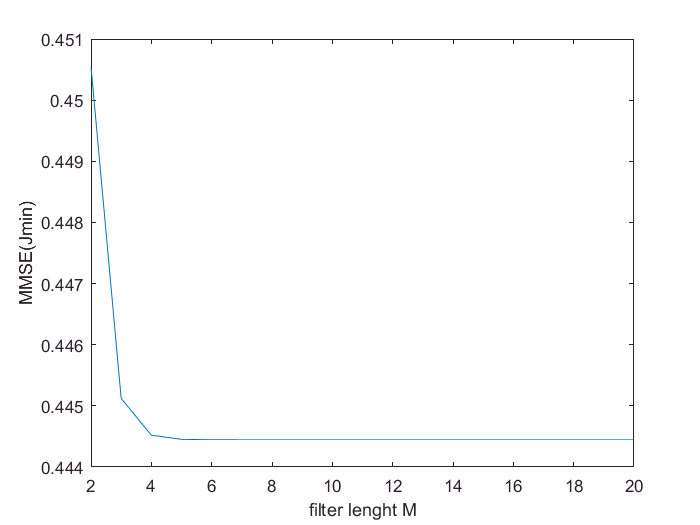

clc;
clear all;
close all;
n=1;
for M=2:20
    k=0:M-1;
    sigmaw2=1;
    rs=0.6.^(abs(k));
    rw=sigmaw2*[1 zeros(1,M-1)];
    rx=rs+rw;
    Rx=toeplitz(rx);
    rdx=rs;
    h=inv(Rx)*rdx';
    Jmin(n)=rdx(1)-rdx*h;
    n=n+1;
end
M=2:20;
plot(M,Jmin);
xlabel('filter lenght M');
ylabel('MMSE(Jmin)');